# Machine Learning Prediction of Side effects for Drugs in Clinical Trials

Diego Galeano, Alberto Paccanaro

clc;close all; clear all;
addpath('data\')
addpath('source\')

#### Read datasets

This .mat file contains all the datasets used in our study

- **ATC. ** contains the associations between drugs and their ATC codes at each of the 4 levels of the ATC hiearchy. The columns are ordered according to **ATC_labels**.

- **ATC_labels**. contains the ATC code at each of the 4 different levels of the ATC hiearchy.

- **DChemMACCS**. contains the MACCS chemical fingerprint of each drug.

- **DInd**. contains the drug-indication associations..

- **DTarget**. contains the drug-target associations.

- **MedDRA**. contains the associations between side effects and MedDRA terms at each of the 3 levels of the MedDRA hiearchy. The columns are ordered according to **MedDRA_labels**.

- **MedDRA_labels**. contains the MedDRA terms at each of the levels of the MedDRA hierarchy.  

- **Xct**. drug side effect matrix association that contains those identified in clinical trials.

- **Xpost**. postmarketing side effect associations from SIDER 4.1

- **Xoffs**. postmarketing drug side effect associations from OFFSIDES.

- **reduced_SE_names**. contains the side effect names.

- **reduced_drug_names**. contains the drug names.

data = load('data/data_experiments.mat');

The graph information is store in two separate cell formats

- **GDrugs**. contains in each element a drug-drug similarity matrix. {1} chemical similarity; {2} indication similarity; {3} target similarity; {4} ATC taxonomy similarity.

- **GSE**. contains in each element a side effect-side effect similarity matrix. {1} MedDRA taxonomy similarity. 

load('data/graph_information.mat', 'GDrugs', 'GSE');

Data from clinical trials

Xct = double(data.Xct > 0);
[ndrugs, nses] = size(Xct);

Postmarketing data

X_postmarket_sider = data.Xpost > 0;
X_postmarket_offsides = data.Xoffs > 0;

Xtrain =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     1     0     0     1     1     0     0     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0     1     0     0     1     0     0     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     1     0     0     0     0     0    

#### GSEM model hyperparameters

maxiter = 500;


 iter: 32, dw = 9.469347e-03 


myl2_drugs = 60;
myl1_drugs = 0;
alpha_drugs = [0.1 0.5 0.01 5.0];


 iter: 47, dw = 9.519430e-03 


myl2_se = 40;
myl1_se = 0.5;
alpha_se = 0.5;

#### Train GSEM on all the available data

% we used all the data for training
Xtrain = double(Xct > 0 | X_postmarket_sider > 0 | X_postmarket_offsides > 0)

[ H ] = GSEM( Xtrain', GDrugs, alpha_drugs, myl2_drugs, myl1_drugs); 
                            
    
[ W ] = GSEM( Xtrain, GSE, alpha_se, myl2_se, myl1_se);
    
Xhat = (Xct'*H)' + Xct*W; 

### Analysis of prediction for a drug-side effect pair

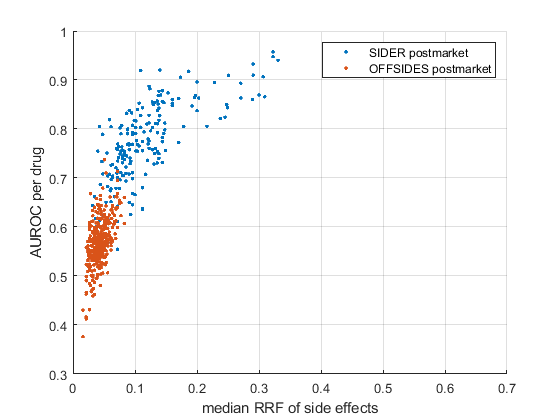

selected_drug = 'metformin';

% find the index of this drug to extract predictions
idx_drug = find(strcmp(data.reduced_drug_names, selected_drug));

selected_SE = 'metformin';
% find the index of this drug to extract predictions
idx_SE = find(strcmp(data.reduced_drug_names, selected_drug));